# Figure S3B

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A051_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 20×5 cell array
    {'siCCNA2 DOX'     }    {[2 3 4]}    {[2]}    {[1]}    {[0]}
    {'siCCNA2 DMSO'    }    {[5 6 7]}    {[2]}    {[1]}    {[0]}
    {'siCCNB1/2 DOX'   }    {[2 3 4]}    {[3]}    {[1]}    {[0]}
    {'siCCNB1/2 DMSO'  }    {[5 6 7]}    {[3]}    {[1]}    {[0]}
    {'siCCNE1/2 DOX'   }    {[2 3 4]}    {[4]}    {[1]}    {[0]}
    {'siCCNE1/2 DMSO'  }    {[5 6 7]}    {[4]}    {[1]}    {[0]}
    {'siCdc25a DOX'    }    {[2 3 4]}    {[5]}    {[1]}    {[0]}
    {'siCdc25a DMSO'   }    {[5 6 7]}    {[5]}    {[1]}    {[0]}
    {'siA+B DOX'       }    {[2 3 4]}    {[6]}    {[1]}    {[0]}
    {'siA+B DMSO'      }    {[5 6 7]}    {[6]}    {[1]}    {[0]}
    {'siA+E DOX'       }    {[2 3 4]}    {[7]}    {[1]}    {[0]}
    {'siA+E DMSO'      }    {[5 6 7]}    {[7]}    {[1]}    {[0]}
    {'siE+B DOX'       }    {[2 3 4]}    {[8]}    {[1]}    {[0]}
    {'siE+B  DMSO'     }    {[5 6 7]}    {[8]}    {[1]}    {[0]}
    {'siCDC25a+A DOX'  }    {[2 3 4]}    {[9]}    {[1]}    {[

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,2)),1);
    apcGateAll = false(length(dat.POI(:,2)),1); 
     crlGate = false(length(dat.POI(:,3)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
                       apcExpressGate(n) = nanmean(dat.apcNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) <.1;
        end

        if dat.POI(n,3) + round(4*framesPerHr) <= numFrames 
            crlGate(n) = nanmean(dat.cdk(n,dat.POI(n,3) + [-1* framesPerHr: -.5* framesPerHr] )) < .5 & ...
                nanmean(dat.cdk(n,dat.POI(n,3) + [round(.5* framesPerHr): 1* framesPerHr] )) < .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
        S(i).apcGate = apcGate;
S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;


end

conds=[20 2 4];
timeGate = [0 3];
colors = [.1 .4 1; .6 .9 .2;.9 .7 .9;.1 .1 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 2;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).goodCdk& S(conds(i)).POI_realtime(:,1) >= timeGate(1);
sum(inds)
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',2});
end

ans = 1333

ans = 491

ans = 666

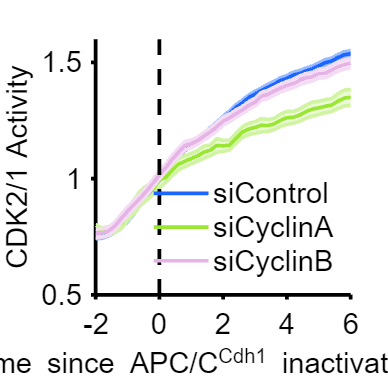

set(gca,'linewidth',2,'fontsize',16)
ylabel({'CDK2/1 Activity'});
xlabel('Time since APC/C^{Cdh1} inactivation (h)');
legend('siControl','siCyclinA','siCyclinB','box','off','Location','southeast','fontsize',16);

xlim([-2 6]); 
ylim([.5 1.6]);
vline([0],'k--')

% print_pdf(['fig_S3B.pdf'])